Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Debunching and rebunching on a higher harmonic (Section 5.5)

Volker Ziemann, 211112, CC-BY-SA-4.0

**Important:** requires the elliptic package from [https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic) located in a subdirectory below the present one (for the fast evaluation of elliptic functions).

In this simulation we first cerate a matched longitudinal distribution, then reduce the RF-voltage adiabatically to zero, which spreads out the bunch longitudinally. At that point we turn on and increase the voltage of an RF-system at a higher harmonic, which causes the particles to rebunch into several bunchlets.

## Matched distribution

In the first step we define the parameters of the system and the initial particle distribution that is randomly distributed in a short range of phases and momenta and displayed as a cloud of green dots. Then we move the coordinates of each particle forward in time by $100$ synchrotron periods, which causes the initial distribution to smear out into a matched longitudinal distribution, shown by the red dots. Note that we also superimpose the separatrix determined by the initial value of $\Omega_s$.

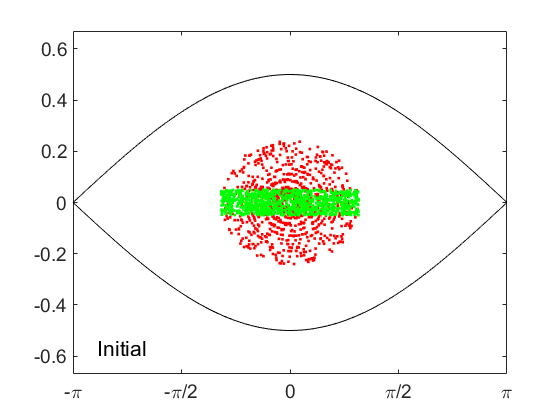

clear all; close all
addpath ./elliptic
Omegas=0.25; Ts=2*pi/Omegas; % synchrotron frequency
dt=100*Ts;   % or 100*Ts   % <--- set time here
N=1000;      % number of particles
x0=[0.0,0.0]; dx=[2.0,0.1];  % center and spread of initialdistribution
phi=-pi:0.01:pi; separatrix=2*Omegas*cos(0.5*phi);
hold off; plot(phi,separatrix,'k',phi,-separatrix,'k')
axis([-pi,pi,-0.67,0.67]); hold on; pause(0.001)
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
  'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
text(-2.8,-0.57,'Initial','fontsize',16)
x=zeros(N,2); x1=x;
for k=1:N   % loop over particles
  x(k,:)=x0+(rand(1,2)-0.5).*dx; 
  x1(k,:)=pendulumtracker(x(k,:),Omegas,dt); % initial distribution
end
plot(x1(:,1),x1(:,2),'r.')
plot(x(:,1),x(:,2),'g.');

x=x1;   % save matched distribution for later

## Debunching

Now we reduce $\Omega_s$ to zero, which corresponds to reducing the RF-voltage to zero. This is visible by the shrinking separatrix. At the same time the particle distribution increases in the phase-direction and shrinks in the momentum-direction. At the end we are left with an un-bunched beam.

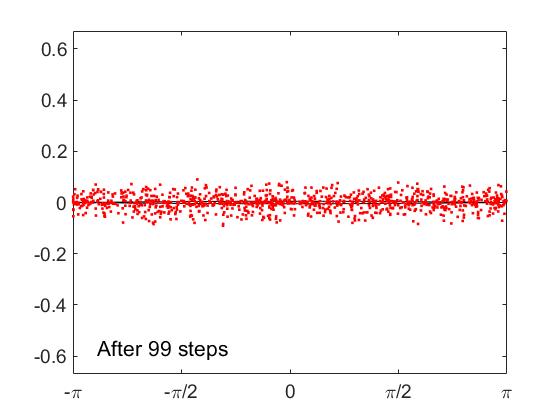

nstep=100; 
for nb=1:nstep-1
  hold off; 
  Omegas=0.25*(nstep-nb)/nstep; Ts=2*pi/Omegas; dt=100*Ts;
  phi=-pi:0.01:pi; separatrix=2*Omegas*cos(0.5*phi);
  plot(phi,separatrix,'k',phi,-separatrix,'k');
  hold on
  parfor k=1:N   % loop over particles, or use "for"
    x1(k,:)=pendulumtracker(x1(k,:),Omegas,dt);
  end
  plot(x1(:,1),x1(:,2),'r.')
  axis([-pi,pi,-0.67,0.67]);
  set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
     'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
  text(-2.8,-0.57,['After ',num2str(nb,'%4d'),' steps'],'fontsize',16) 
  %if nb==50 return; end
  pause(0.001)
end

## Rebunching at  a higher harmonic

Once the beam is unbunched, we turn on an RF system at the second harmonic and increase its voltage, which we simulate by increasing $\Omega_s$. We find that the particles assemble into two separate bunches, each having half the length of the original bunch.

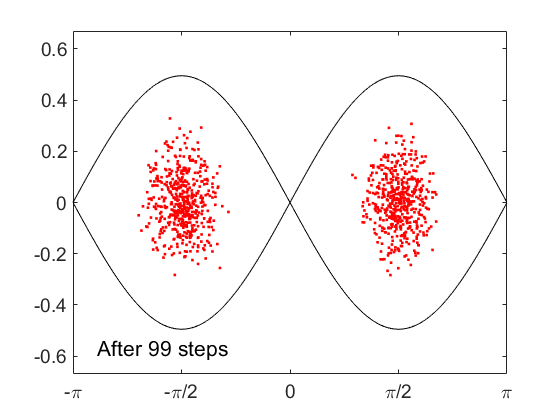

nharm=2;                       % rebunching harmonic
phase0=(1+mod(nharm,2))*pi/2;  % fit separatrices in window
for m=1:nstep-1
  hold off; 
  Omegas=0.25*m/nstep; Ts=2*pi/Omegas; dt=100*Ts;
  phi=-pi:0.01:pi; separatrix=2*Omegas*cos(0.5*phi*nharm+phase0);
  plot(phi,separatrix,'k',phi,-separatrix,'k');
  hold on
  for k=1:N  
    nb=floor(mod(nharm*(x1(k,1)+pi)/(2*pi),nharm));  % which bucket?
    x1(k,1)=(x1(k,1)+pi)*nharm-pi*(2*nb+1);
    x1(k,:)=pendulumtracker(x1(k,:),Omegas,dt);
    x1(k,1)=(x1(k,1)+pi*(2*nb+1))/nharm-pi;
  end
  plot(x1(:,1),x1(:,2),'r.')
  axis([-pi,pi,-0.67,0.67]);
  set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
     'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
  text(-2.8,-0.57,['After ',num2str(m,'%4d'),' steps'],'fontsize',16) 
  pause(0.001)
  %if m==50 return; end
end

% plot(x(:,1),x(:,2),'g.'); % superimpose initial, if desired

It is straightforward to play with  parameters, for example re-bunch into the third harmonic.

## Appendix 

The function` pendulumtracker()` receives the phase-space coordinates `x` at the start, the small-amplitude synchrotron frequency `omega`, and the integration time `dt` as input and returns the phase-space coordinates `xout`. Internally, it integrates the equations of motion for a mathematical pendulum in closed form using Jacobi elliptic functions. This is much faster than numerically integration, expecially for extremely large times, such as thousands or even millions of synchrotron periods. The coding closely follows Section 5.4, especially Equations 5.50 to 5.54. Here we use the elliptic functions from [https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic).

function xout=pendulumtracker(x,omega,dt)
k2=(0.5*x(2)/omega)^2+sin(0.5*x(1))^2; k=sqrt(k2);
if (x(1)>pi) x(1)=x(1)-2*pi; end
if (x(1)<-pi) x(1)=x(1)+2*pi; end
s=1; if (x(1)<0) s=-s; x(1)=-x(1); end
s1=1; if (x(2)<0) s1=-s1; end
if (k>1)   % outside separatrix
  kelf=ellipke(1/k2);
  trev=2*kelf/(k*omega);
  t0=mod(dt,trev);
  tmp=s1*k*omega*t0+s*elliptic12(0.5*x(1),1/k2);
  [sn,cn,dn]=ellipj(tmp,1/k2);  
  if (abs(tmp) > kelf) sn=-sn; end
  xout(1)=2*asin(sn);
  xout(2)=2*s1*omega*k*dn;
else       % inside separatrix
  trev=4*ellipke(k2)/omega;
  t0=mod(dt,trev);
  z0=asin(min(1,sin(0.5*x(1))/k));
  tmp=s1*omega*t0+s*elliptic12(z0,k2);
  [sn,cn,dn]=ellipj(tmp,k2);   
  xout(1)=2*asin(k*sn);
  xout(2)=2*s1*omega*k*cn;
end
end
